load('proj3Data.mat');

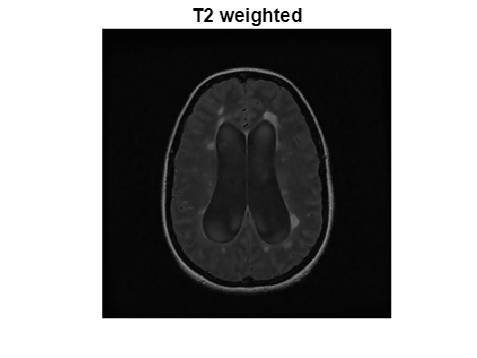

figure
intLimits_v = [min(t1w_m(:)), max(t1w_m(:))];
imagesc(squeeze(t2w_m(:, :, 1)), intLimits_v)
axis image
axis off
colormap(gray)
title('T2 weighted')

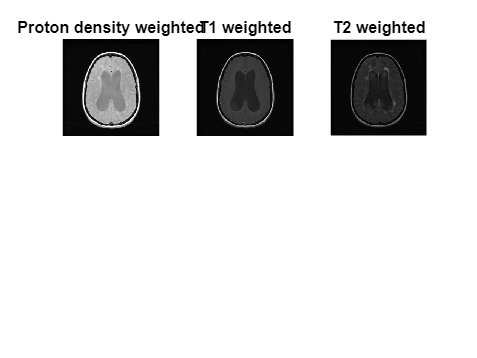

figure
subplot(2, 3, 2)
intLimits_v = [min(t1w_m(:)), max(t1w_m(:))];
imagesc(squeeze(t1w_m(:, :, 1)), intLimits_v)
axis image
axis off
colormap(gray)
title('T1 weighted')

subplot(2, 3, 3)
imagesc(squeeze(t2w_m(:, :, 1)), intLimits_v)
axis image
axis off
colormap(gray)
title('T2 weighted')

subplot(2, 3, 1)
imagesc(squeeze(pdw_m(:, :, 1)),intLimits_v)
axis image
axis off
colormap(gray)
title('Proton density weighted')

nTrain = 6;
t2Max = max(t2w_m(:));
red0_m = t2w_m/t2Max;
green0_m = t2w_m/t2Max;
blue0_m = t2w_m/t2Max;
color_3d = cat(3, red0_m, green0_m, blue0_m);


figure
imagesc(color_3d)
colormap(gray)
axis image
%------------------ Leison points -----------------------
disp(['Click on ', num2str(nTrain), ' lesion points'])

Click on 6 lesion points


[xl_v, yl_v] = ginput(nTrain);   % get at multiple locations to gain some robustness
rowl_v = round(yl_v);
coll_v = round(xl_v);
indexl_v = sub2ind(size(t2w_m), rowl_v, coll_v);

% --------------------- White matter ----------------------
disp(['Click on ', num2str(nTrain), ' white matter points'])

Click on 6 white matter points


[xw_v, yw_v] = ginput(nTrain);   % get at multiple locations to gain some robustness
roww_v = round(yw_v);
colw_v = round(xw_v);
indexw_v = sub2ind(size(t2w_m), roww_v, colw_v);

% --------------------- Grey matter ----------------------
disp(['Click on ', num2str(nTrain), ' grey matter points'])

Click on 6 grey matter points


[xg_v, yg_v] = ginput(nTrain);   % get at multiple locations to gain some robustness
rowg_v = round(yg_v);
colg_v = round(xg_v);
indexg_v = sub2ind(size(t2w_m), rowg_v, colg_v);

% --------------------- CSF ----------------------
disp(['Click on ', num2str(nTrain), ' CSF points'])
[xc_v, yc_v] = ginput(nTrain);   % get at multiple locations to gain some robustness
rowc_v = round(yc_v);
colc_v = round(xc_v);
indexc_v = sub2ind(size(t2w_m), rowc_v, colc_v);

%----------------------
redl_m = red0_m;
greenl_m = green0_m;
bluel_m = blue0_m;

redl_m(indexl_v) = 1;
greenl_m(indexl_v) = 0;
bluel_m(indexl_v) = 0;
color_3d = cat(3, redl_m, greenl_m, bluel_m);

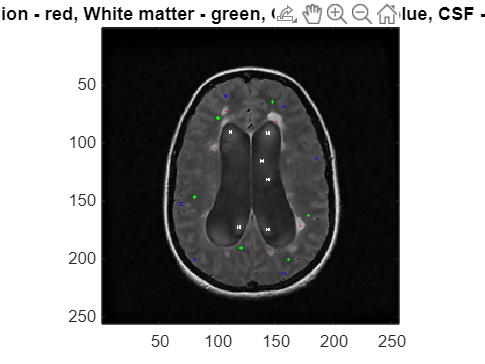


color_3dlwgc = insertMarker(color_3d,[colw_v,roww_v],'+','color','green','size',1);
color_3dlwgc = insertMarker(color_3dlwgc,[colg_v,rowg_v],'x','color','blue','size',1);
color_3dlwgc = insertMarker(color_3dlwgc,[colc_v,rowc_v],'*','color','white','size',1);

figure
image(color_3dlwgc)
axis image
title('Leision - red, White matter - green, Gray matter - blue, CSF - white')

t2wl_v = t2w_m(indexl_v);	% T2 weighted intensity for lesion points.
pdwl_v = pdw_m(indexl_v);	% PD weighted intensity for lesion points.
t1wl_v = t1w_m(indexl_v);   % T1 weighted intensity for lesion points.
t2wl = mean(t2wl_v)

t2wl = 323.5000

pdwl = mean(pdwl_v)

pdwl = 770.3333

t1wl = mean(t1wl_v)

t1wl = 225.5000

t2ww_v = t2w_m(indexw_v);	% T2 weighted intensity.
pdww_v = pdw_m(indexw_v);   % PD weighted intensity.
t1ww_v = t1w_m(indexw_v);
t2ww = mean(t2ww_v)

t2ww = 140.5000

pdww = mean(pdww_v)

pdww = 669

t1ww = mean(t1ww_v)

t1ww = 228.5000

t2wg_v = t2w_m(indexg_v);	% T2 weighted intensity for lesion points.
pdwg_v = pdw_m(indexg_v);
t1wg_v = t1w_m(indexg_v);
t2wg = mean(t2wg_v)

t2wg = 180.1667

pdwg = mean(pdwg_v)

pdwg = 698.5000

t1wg = mean(t1wg_v)

t1wg = 209.1667

t2wc_v = t2w_m(indexc_v);	% T2 weighted intensity for lesion points.
pdwc_v = pdw_m(indexc_v);
t1wc_v = t1w_m(indexc_v);
t2wc = mean(t2wc_v)

t2wc = 154.3333

pdwc = mean(pdwc_v)

pdwc = 530.3333

t1wc = mean(t1wc_v)

t1wc = 132.8333

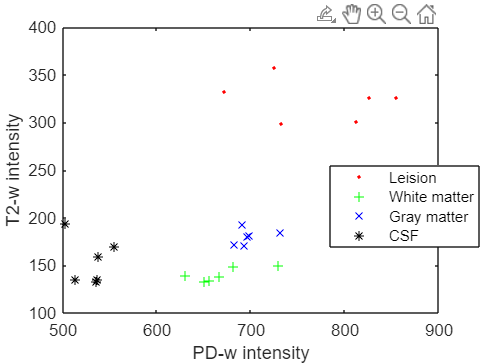

figure
plot(pdwl_v, t2wl_v, 'r.', pdww_v, t2ww_v, 'g+', ...
    pdwg_v, t2wg_v, 'bx', pdwc_v, t2wc_v, 'k*')
xlabel('PD-w intensity')
ylabel('T2-w intensity')
legend('Leision','White matter', 'Gray matter', 'CSF')

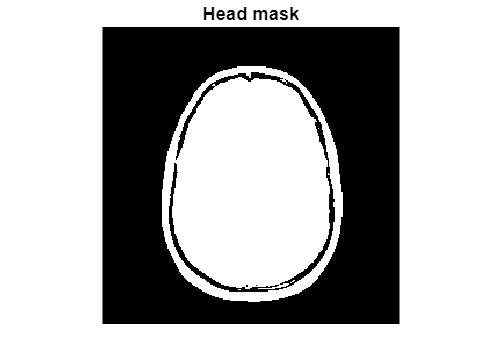

% Create head mask
pdMax = max(pdw_m(:));
mask_m = (pdw_m > 0.1*pdMax);
figure
imagesc(mask_m)
colormap(gray)
axis image
axis off
title('Head mask')

index2_v = find(mask_m(:));
t2wHead_v = t2w_m(index2_v);
pdwHead_v = pdw_m(index2_v);
nHeadPixels = length(index2_v);

lesionMask_m = zeros(256, 256);
wmMask_m = zeros(256, 256);
gmMask_m = zeros(256, 256);
csfMask_m = zeros(256, 256);
for pixel = 1:nHeadPixels
    % Find intensities for current pixel:
    t2w = t2wHead_v(pixel);
    pdw = pdwHead_v(pixel);

    % Insert code here to find the distance in feature space
    % between the current point at coordinates (pdw, t2w)
    % and the mean position of the training points for each
    % of the four pixel types (lesion, white matter, gray matter,
    % and cerebral spinal fluid).
    p2l = pdist([t2w,pdw;t2wl,pdwl]);
    p2w = pdist([t2w,pdw;t2ww,pdww]);
    p2g = pdist([t2w,pdw;t2wg,pdwg]);
    p2c = pdist([t2w,pdw;t2wc,pdwc]);
    % Insert code here to find which pixel type the current 
    % point is closest to. 
    [val,idx] = min([p2l,p2w,p2g,p2c]);
    
     % Make the (row, col) element of the corresponding tissue
    %  mask (lesionMask_m, etc) equal to 1. Note that the 
    % current pixel’s position in the image is given by
    [row, col] = ind2sub(size(t2w_m), index2_v(pixel));
    switch idx
        case 1
            lesionMask_m(row,col) = 1;
        case 2
            wmMask_m(row,col) = 1;
        case 3
            gmMask_m(row,col) = 1;
        otherwise
            csfMask_m(row,col) = 1;
    end
end

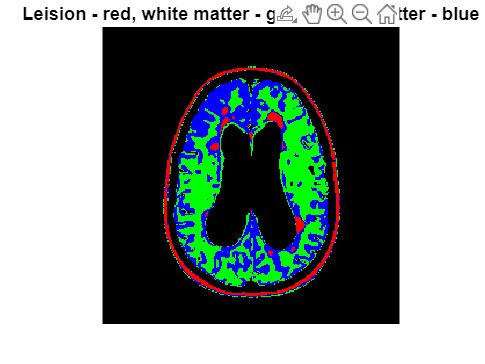

figure
image(cat(3, lesionMask_m, wmMask_m, gmMask_m))
title('Leision - red, white matter - green, gray matter - blue')
axis image
axis off

disp('Define a polygon enclosing brain, excluding extracranial fat')

Define a polygon enclosing brain, excluding extracranial fat


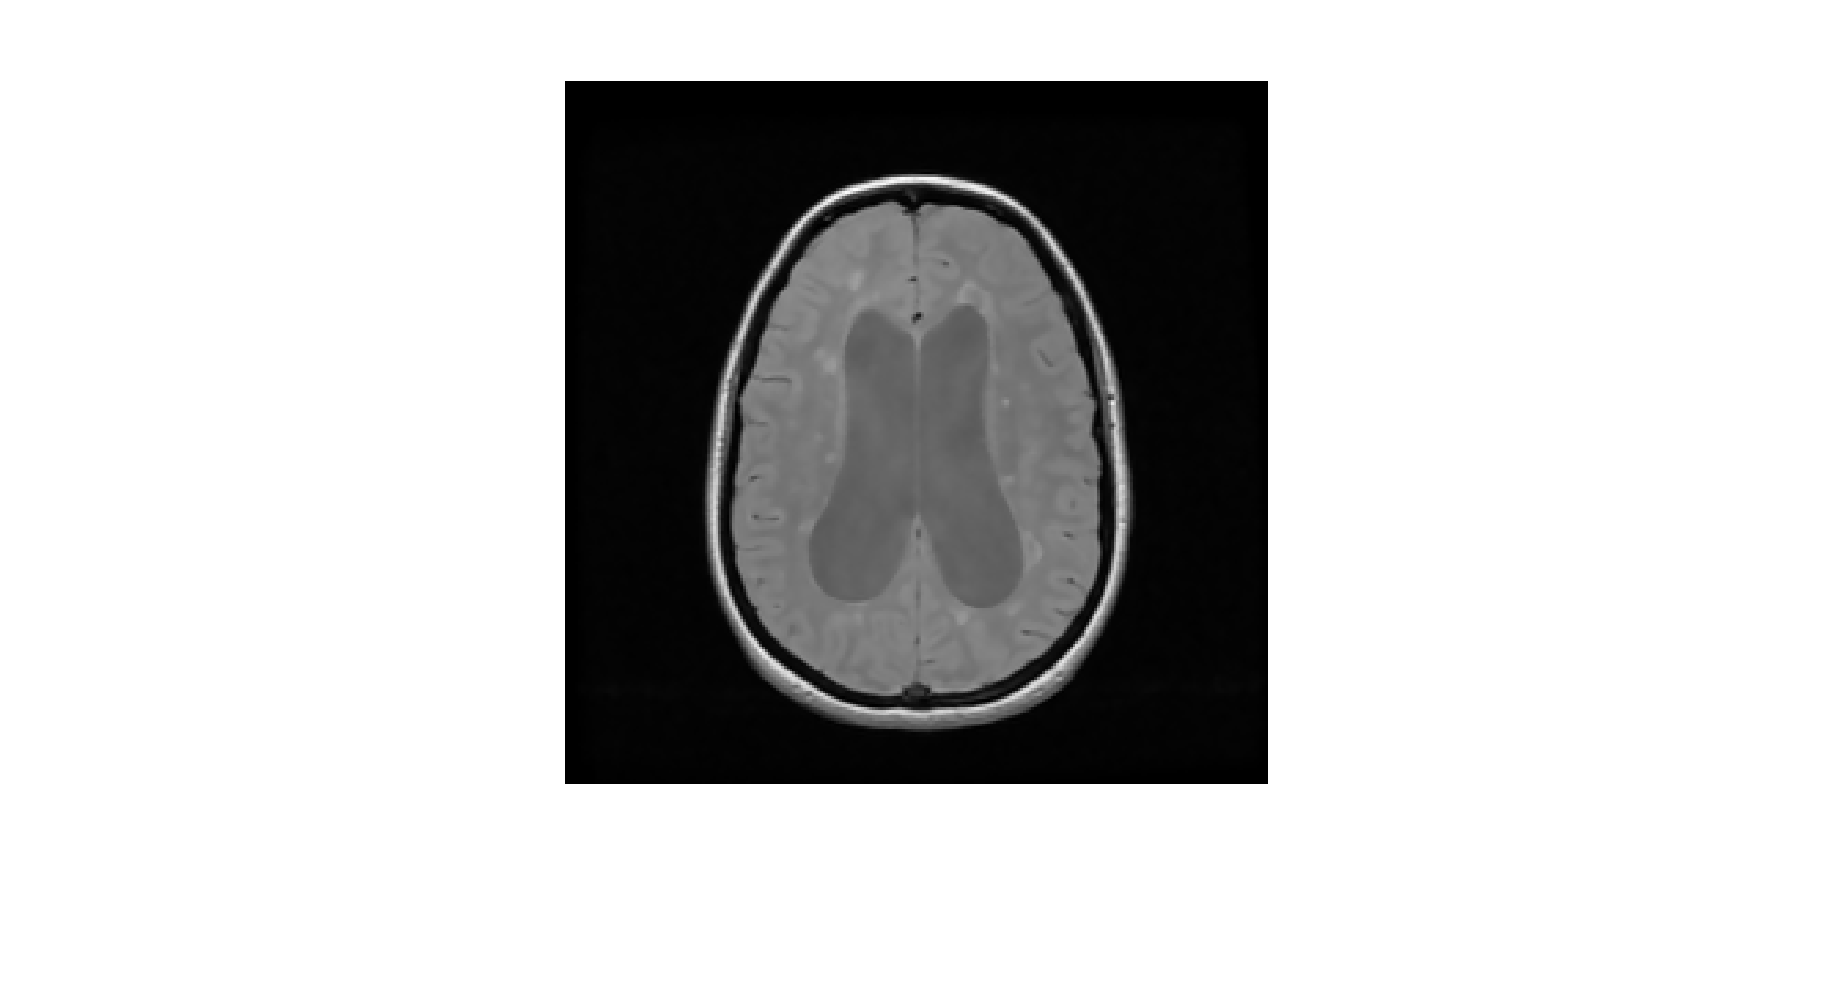

skullMask_m = roipoly(pdw_m / pdMax);

% Zero all pixels outside the skull:
lesionMask_m = skullMask_m .* lesionMask_m;
wmMask_m = skullMask_m .* wmMask_m;
gmMask_m = skullMask_m .* gmMask_m;

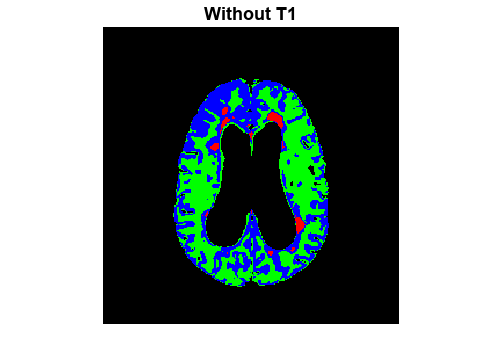


% Display improved segmentation map:
figure
image(cat(3, lesionMask_m, wmMask_m, gmMask_m))
title('Without T1')
axis image
axis off

% Find the total number of lesion pixels by adding all the 1 s in the lesionMask_m matrix.
length(find(lesionMask_m))

ans = 356

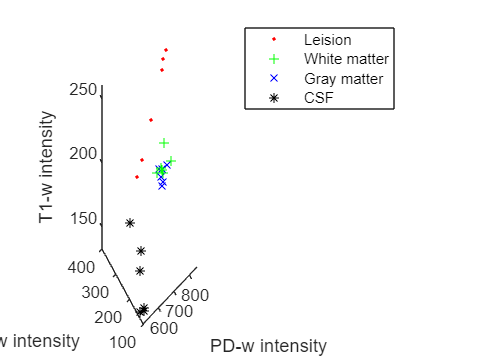

%	Find the T1 weighted image intensity for each training point (above)
figure
plot3(pdwl_v, t2wl_v, t1wl_v, 'r.', pdww_v, t2ww_v, t1ww_v, 'g+', ...
    pdwg_v, t2wg_v, t1wg_v, 'bx', pdwc_v, t2wc_v, t2wc_v, 'k*')
xlabel('PD-w intensity')
ylabel('T2-w intensity')
zlabel('T1-w intensity')
legend('Leision','White matter', 'Gray matter', 'CSF')

%---------------------------- Add on T1 weighting

index2_v = find(mask_m(:));
t2wHead_v = t2w_m(index2_v);
pdwHead_v = pdw_m(index2_v);
t1wHead_v = t1w_m(index2_v);
nHeadPixels = length(index2_v);

lesionMaskT1_m = zeros(256, 256);
wmMaskT1_m = zeros(256, 256);
gmMaskT1_m = zeros(256, 256);
csfMaskT1_m = zeros(256, 256);
for pixel = 1:nHeadPixels
    % Find intensities for current pixel:
    t2w = t2wHead_v(pixel);
    pdw = pdwHead_v(pixel);
    t1w = t1wHead_v(pixel);

    % Insert code here to find the distance in feature space
    % between the current point at coordinates (pdw, t2w)
    % and the mean position of the training points for each
    % of the four pixel types (lesion, white matter, gray matter,
    % and cerebral spinal fluid).
    p2l = squareform(pdist([t2w,pdw,t1w;t2wl,pdwl,t1wl]));
    p2w = squareform(pdist([t2w,pdw,t1w;t2ww,pdww,t1ww]));
    p2g = squareform(pdist([t2w,pdw,t1w;t2wg,pdwg,t1wg]));
    p2c = squareform(pdist([t2w,pdw,t1w;t2wc,pdwc,t1wc]));
    % Insert code here to find which pixel type the current 
    % point is closest to. 
    [val,idx] = min([p2l(2),p2w(2),p2g(2),p2c(2)]);
    
     % Make the (row, col) element of the corresponding tissue
    %  mask (lesionMask_m, etc) equal to 1. Note that the 
    % current pixel’s position in the image is given by
    [row, col] = ind2sub(size(t2w_m), index2_v(pixel));
    switch idx
        case 1
            lesionMaskT1_m(row,col) = 1;
        case 2
            wmMaskT1_m(row,col) = 1;
        case 3
            gmMaskT1_m(row,col) = 1;
        otherwise
            csfMaskT1_m(row,col) = 1;
    end
end

ans = 567.0507

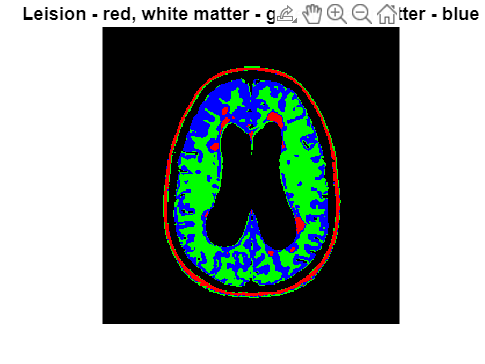

figure
image(cat(3, lesionMaskT1_m, wmMaskT1_m, gmMaskT1_m))
title('Leision - red, white matter - green, gray matter - blue')
axis image
axis off

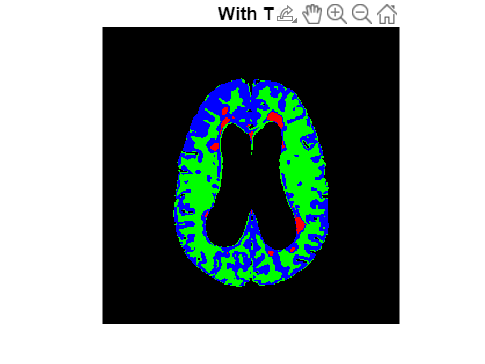

% disp('Define a polygon enclosing brain, excluding extracranial fat')
% skullMask_m = roipoly(pdw_m / pdMax);
% Zero all pixels outside the skull:
lesionMaskT1_m = skullMask_m .* lesionMaskT1_m;
wmMaskT1_m = skullMask_m .* wmMaskT1_m;
gmMaskT1_m = skullMask_m .* gmMaskT1_m;
% Display improved segmentation map:
figure
image(cat(3, lesionMaskT1_m, wmMaskT1_m, gmMaskT1_m))
title('With T1')
axis image
axis off

% Find the total number of lesion pixels by adding all the 1 s in the lesionMask_m matrix.
length(find(lesionMaskT1_m))

ans = 367